# ***Question1***

***1 a)***

N=10000;
h=@(x)dualBearingMeasurement(x, [0;100],[100;0]);

Y_1=generatenonlinearsample([125;125],[100,0;0,25],h,((0.1*pi)/180)^2,N);
[mu_1, Sigma_1] = get_mean_cov(Y_1);
Y_2=generatenonlinearsample([-25;125],[100,0;0,25],h,((0.1*pi)/180)^2,N);
[mu_2, Sigma_2] = get_mean_cov(Y_2);
Y_3=generatenonlinearsample([60;60],[100,0;0,25],h,((0.1*pi)/180)^2,N);
[mu_3, Sigma_3] = get_mean_cov(Y_3);

***1 b)***

%for case1:
[mu_1E,Sigma_1E] = nonLinKFprediction([125;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'EKF');
[mu_1U,Sigma_1U] = nonLinKFprediction([125;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'UKF');
[mu_1C,Sigma_1C] = nonLinKFprediction([125;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'CKF');
%for case2:
[mu_2E,Sigma_2E] = nonLinKFprediction([-25;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'EKF');
[mu_2U,Sigma_2U] = nonLinKFprediction([-25;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'UKF');
[mu_2C,Sigma_2C] = nonLinKFprediction([-25;125],[100,0;0,25],h, ((0.1*pi)/180)^2, 'CKF');
%for case3:
[mu_3E,Sigma_3E] = nonLinKFprediction([60;60],[100,0;0,25],h,((0.1*pi)/180)^2,'EKF');
[mu_3U,Sigma_3U] = nonLinKFprediction([60;60],[100,0;0,25],h, ((0.1*pi)/180)^2,'UKF');
[mu_3C,Sigma_3C] = nonLinKFprediction([60;60],[100,0;0,25],h,((0.1*pi)/180)^2,'CKF');

 %get the ellipse
 [xy_1] = sigmaEllipse2D( mu_1, Sigma_1, 3, 1000 );
 [xy_1E] = sigmaEllipse2D( mu_1E, Sigma_1E, 3, 1000 );
 [xy_1U] = sigmaEllipse2D( mu_1U, Sigma_1U, 3, 1000 );
 [xy_1C] = sigmaEllipse2D( mu_1C, Sigma_1C, 3, 1000 );

 [xy_2] = sigmaEllipse2D( mu_2, Sigma_2, 3, 1000 );
 [xy_2E] = sigmaEllipse2D( mu_2E, Sigma_2E, 3, 1000 );
 [xy_2U] = sigmaEllipse2D( mu_2U, Sigma_2U, 3, 1000 );
 [xy_2C] = sigmaEllipse2D( mu_2C, Sigma_2C, 3, 1000 );

 [xy_3] = sigmaEllipse2D( mu_3, Sigma_3, 3, 1000 );
 [xy_3E] = sigmaEllipse2D( mu_3E, Sigma_3E, 3, 1000 );
 [xy_3U] = sigmaEllipse2D( mu_3U, Sigma_3U, 3, 1000 );
 [xy_3C] = sigmaEllipse2D( mu_3C, Sigma_3C, 3, 1000 );

***1c）***

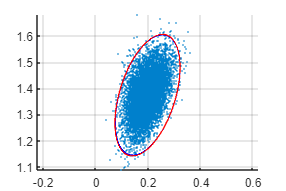

%for case one
figure('Position',[300 300 600 400]);

% subplot(3,1,1)
scatter(Y_1(1,:),Y_1(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_1(1,:),xy_1(2,:),'color','blue','LineWidth',1);
plot(xy_1E(1,:),xy_1E(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

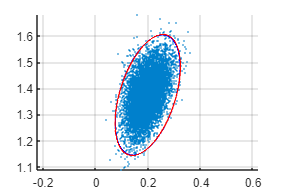


figure('Position',[300 300 600 400]);

% subplot(3,1,2)
scatter(Y_1(1,:),Y_1(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_1(1,:),xy_1(2,:),'color','blue','LineWidth',1);
plot(xy_1U(1,:),xy_1U(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

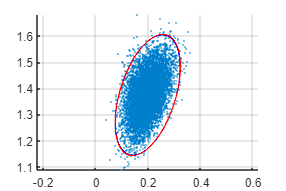


figure('Position',[300 300 600 400]);

% subplot(3,1,3)
scatter(Y_1(1,:),Y_1(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_1(1,:),xy_1(2,:),'color','blue','LineWidth',1);
plot(xy_1C(1,:),xy_1C(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

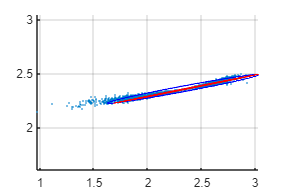


%for case two
figure('Position',[300 300 600 400]);
% subplot(3,1,1)
scatter(Y_2(1,:),Y_2(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_2(1,:),xy_2(2,:),'color','blue','LineWidth',1);
plot(xy_2E(1,:),xy_2E(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

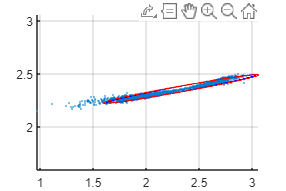


figure('Position',[300 300 600 400]);

% subplot(3,1,2)
scatter(Y_2(1,:),Y_2(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_2(1,:),xy_2(2,:),'color','blue','LineWidth',1);
plot(xy_2U(1,:),xy_2U(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

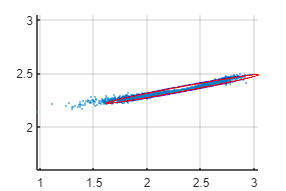


figure('Position',[300 300 600 400]);

% subplot(3,1,3)
scatter(Y_2(1,:),Y_2(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_2(1,:),xy_2(2,:),'color','blue','LineWidth',1);
plot(xy_2C(1,:),xy_2C(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

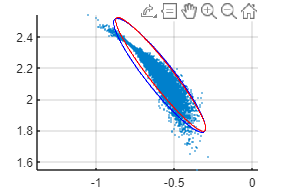



%for case three
figure('Position',[300 300 600 400]);

% subplot(1,3,1)
scatter(Y_3(1,:),Y_3(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_3(1,:),xy_3(2,:),'color','blue','LineWidth',1);
plot(xy_3E(1,:),xy_3E(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

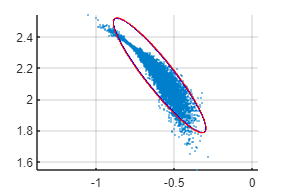


figure('Position',[300 300 600 400]);

% subplot(1,3,2)
scatter(Y_3(1,:),Y_3(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_3(1,:),xy_3(2,:),'color','blue','LineWidth',1);
plot(xy_3U(1,:),xy_3U(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

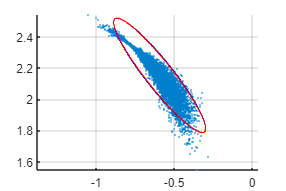


figure('Position',[300 300 600 400]);

% subplot(1,3,3)
scatter(Y_3(1,:),Y_3(2,:),2,'filled', 'MarkerFaceColor', [0 0.5 0.8]);
hold on

plot(xy_3(1,:),xy_3(2,:),'color','blue','LineWidth',1);
plot(xy_3C(1,:),xy_3C(2,:),'color','red','LineWidth',1);
axis equal
grid on
hold off

# ***Question 2***

***2 a)***

%For case 1 define initial state and varience
x_0=[0,0,20,0,((5*pi)/180)^2]';
P_0=diag([10^2,10^2,2^2,(pi/180)^2,(pi/180)^2]);

sigma_v=1;
sigma_w=pi/180;
sigma_phi1=2*pi/180;
sigma_phi2=2*pi/180;
Q=[0 0 0 0 0;
   0 0 0 0 0;
   0 0 (sigma_v)^2 0 0;
   0 0 0 0 0;
   0 0 0 0 (sigma_w)^2];
R=[sigma_phi1^2 0;
    0 sigma_phi2^2];

%define two nonlinear function
f=@(x)coordinatedTurnMotion(x, 1);
h=@(x)dualBearingMeasurement(x,[-200;100],[-200;-100]);


%firstly get sequences of N=100
N=100;
X_s = genNonLinearStateSequence(x_0, P_0, f, Q, N);
Y_s = genNonLinearMeasurementSequence(X_s, h, R);

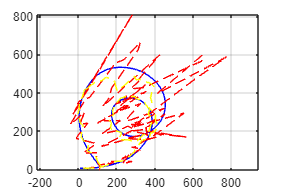


%get nonlinearKF result 
[x_cs1_E, P_cs1_E, ~, ~] = nonLinearKalmanFilter    (Y_s, x_0, P_0, f, Q, h, R, 'EKF');
[x_cs1_U, P_cs1_U, ~, ~] = nonLinearKalmanFilter(Y_s, x_0, P_0, f, Q, h, R, 'UKF');
[x_cs1_C, P_cs1_C, ~, ~] = nonLinearKalmanFilter(Y_s, x_0, P_0, f, Q, h, R, 'CKF');
% change angle to position for  the measurement 
X_mesure=[];
for i=1:length(Y_s)
[x, y] = getPosFromMeasurement(Y_s(1,i), Y_s(2,i), [-200;100],[-200;-100]);
a=[x;y];
X_mesure=[X_mesure,a];
end


%get 3σ-contours every five times

SE=[];
for j=1:5:size(x_cs1_E,2)
     [s] = sigmaEllipse2D (x_cs1_E(1:2,j),P_cs1_E(1:2,1:2,j),3, 100);
     SE=[SE,s];
end

SU=[];
for j=1:5:size(x_cs1_U ,2)
     [s] = sigmaEllipse2D (x_cs1_U(1:2,j),P_cs1_U(1:2,1:2,j),3, 100);
     SU=[SU,s];
end

SC=[];
for j=1:5:size(x_cs1_C,2)
     [s] = sigmaEllipse2D (x_cs1_C(1:2,j),P_cs1_C(1:2,1:2,j),3, 100);
     SC=[SC,s];
end




%give the figures 
figure('Position',[300 300 600 400]);
plot(X_s(1,:),X_s(2,:),'b');
hold on
axis equal
plot(X_mesure(1,:),X_mesure(2,:),'r--');
hold on
plot(x_cs1_E(1,:),x_cs1_E(2,:),'Y--');
hold on
plot();
hold off
grid on

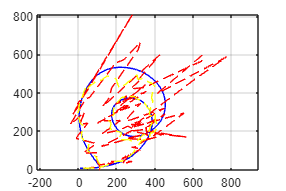



figure('Position',[300 300 600 400]);
plot(X_s(1,:),X_s(2,:),'b');
hold on
plot(X_mesure(1,:),X_mesure(2,:),'r--');
plot(x_cs1_U(1,:),x_cs1_U(2,:),'Y--');



grid on  
axis equal
hold off
 

# ***The functions used in the tasks***

function *generatenonlinearsample *for 1a):

function Y=generatenonlinearsample(mu,Sigma,f,Sigma_r,N)
X_sample=(mvnrnd(mu,Sigma,N))';
R_sample=(mvnrnd(zeros(size(Sigma_r,2),1),Sigma_r,N))';
Y=[];
for i=1:N
[fx,Fx]=f(X_sample(:,i));
y=fx+R_sample(:,i);
Y=[Y,y];
end
end

function *sigmaEllipse2D *for plot in 1b):

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, nPoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
% MU [2 x 1] Mean of the Gaussian density
% SIGMA [2 x 2] Covariance matrix of the Gaussian density
% LEVEL Which sigma level curve to plot. Default = 3.
% NPOINTS Number of points on the ellipse to generate. Default = 32.
%
%Output:
% XY 2 x npoints matrix. First row holds x-coordinates, second
% row holds the y-coordinates.

if nargin < 3
level = 3;
end
if nargin < 4
nPoints = 32;
end

th = linspace(0,2*pi,nPoints);
xy = mu + level*sqrtm(Sigma)*[cos(th); sin(th)];

end

function *getPosFromMeasurement *for 2a):

function [x, y] = getPosFromMeasurement(y1, y2, s1, s2)
%GETPOSFROMMEASUREMENT computes the intersection point
%(transformed 2D measurement in Cartesian coordinate
%system) given two sensor locations and two bearing
%measurements, one from each sensor.
%INPUT: y1: bearing measurement from sensor 1
% y2: bearing measurement from sensor 2
% s1: location of sensor 1 in 2D Cartesian
% s2: location of sensor 2 in 2D Cartesian
%OUTPUT: x: coordinate of intersection point on x axis
% y: coordinate of intersection point on y axis
%This problem can be formulated as solving a set of two
%linear equations with two unknowns. Specifically, one
%would like to obtain (x,y) by solving
%(y−s1(2))=(x−s1(1))tan(y1) and (y−s2(2))=(x−s2(1))tan(y2).
x = (s2(2)-s1(2)+tan(y1)*s1(1)-tan(y2)*s2(1))/(tan(y1)-tan(y2));
y = s1(2)+tan(y1)*(x-s1(1));
end


***otherFunctions***

function [X,Y] =getnormpdf(mu,sigma,a,b)
%this function get the Gaussian distribution figure
% mu and sigma define distribution
% a defines the sampling range, b defines the sampling interval
X=(mu-a):b:(mu+a);
Y=normpdf(X,mu,sigma);

end
function [mu, Sigma] = get_mean_cov(Y)
%this function get the mean and cov of Y
mu=mean(Y,2);
Sigma = zeros(length(mu),length(mu));
for i = 1:length(Y)
    sigma = (Y(:,i)-mu)*(Y(:,i)-mu)';
    Sigma = Sigma+sigma;
end    
Sigma= Sigma/(length(Y)-1);
end

# ***The nonlinear Kalmen filter functions ***

***3.1.5-3.1.8 ***

function [xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, type)
%NONLINEARKALMANFILTER Filters measurement sequence Y using a 
% non-linear Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence for times 1,...,N
%   x_0         [n x 1] Prior mean for time 0
%   P_0         [n x n] Prior covariance
%   f                   Motion model function handle
%                       [fx,Fx]=f(x) 
%                       Takes as input x (state) 
%                       Returns fx and Fx, motion model and Jacobian evaluated at x
%   Q           [n x n] Process noise covariance
%   h                   Measurement model function handle
%                       [hx,Hx]=h(x,T) 
%                       Takes as input x (state), 
%                       Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%

% Your code here. If you have good code for the Kalman filter, you should re-use it here as
% much as possible.
n=length(x_0);
N=length(Y);

xf=zeros(n,N);
Pf=zeros(n,n,N);

xp=zeros(n,N);
Pp=zeros(n,n,N);

x_up=x_0;
P_up=P_0;
for i=1:N
 [x_pre, P_pre] = nonLinKFprediction(x_up, P_up, f, Q, type);
 [x_up, P_up] = nonLinKFupdate(x_pre, P_pre, Y(:,i), h, R, type);
 
 xf(:,i)=x_up;
 Pf(:,:,i)=P_up;
 xp(:,i)=x_pre;
 Pp(:,:,i)=P_pre;
end
end

function [x, P] = nonLinKFupdate(x, P, y, h, R, type)
%NONLINKFUPDATE calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement vector
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state), 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%               Function must include all model parameters for the particular model, 
%               such as sensor position for some models.
%   R           [m x m] Measurement noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%

    switch type
        case 'EKF'
            % Your EKF update here
            [hx,Hx]=h(x);
            S=Hx*P*Hx'+R;
            k=P*Hx'*inv(S);
                       
            x=x+k*(y-hx);
            P=P-k*S*k';
        case 'UKF'
            % Your UKF update here
            [SP,W] = sigmaPoints(x, P, 'UKF');
            n=length(SP);
            
            y_pre=zeros(size(y,1),1);
            for i=1:n
                [hx,~]=h(SP(:,i));
                y_p=hx*W(:,i);
                y_pre=y_pre+y_p;
            end
            p_xy= zeros(length(x),length(y));
            S=R;
            for i=1:n
                [hx,~]=h(SP(:,i));
                p=(SP(:,i)-x)*(hx-y_pre)'*W(:,i);
                p_xy=p_xy+p;
                
                s=(hx-y_pre)*(hx-y_pre)'*W(:,i);
                S=S+s;
            end
            
            x=x+p_xy*inv(S)*(y-y_pre);
            P=P-p_xy*inv(S)*(p_xy)';          
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
            
        case 'CKF'
           [SP,W] = sigmaPoints(x, P, 'CKF');
            n=length(SP);
            
            y_pre=zeros(size(y,1),1);
            for i=1:n
                [hx,~]=h(SP(:,i));
                y_p=hx*W(:,i);
                y_pre=y_pre+y_p;
            end
            p_xy= zeros(length(x),length(y));
            S=R;
            for i=1:n
                [hx,~]=h(SP(:,i));
                p=(SP(:,i)-x)*(hx-y_pre)'*W(:,i);
                p_xy=p_xy+p;
                
                s=(hx-y_pre)*(hx-y_pre)'*W(:,i);
                S=S+s;
            end
            
            x=x+p_xy*inv(S)*(y-y_pre);
            P=P-p_xy*inv(S)*(p_xy)'; 
            
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end
end


function [x, P] = nonLinKFprediction(x, P, f, Q, type)
%NONLINKFPREDICTION calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

    switch type
        case 'EKF'
            [fx,Fx]=f(x);
            x=fx;
            P=Fx*P*Fx'+Q;
        case 'UKF'
            [SP,W] = sigmaPoints(x, P, 'UKF') ;     
            n=length(SP);
            x=zeros(size(x,1),1);
            for i=1:n
                [fx,~]=f(SP(:,i));
                x_u=fx*W(:,i);
                x=x+x_u;
            end
            
            P=Q;
            for i=1:n
                [fx,~]=f(SP(:,i));
                p=(fx-x)*(fx-x)'*W(:,i);
                P=P+p;
            end
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
                
        case 'CKF'
            [SP,W] = sigmaPoints(x, P, 'CKF');
            % Your CKF code here
            n=length(SP);
            x=zeros(size(x,1),1);
            for i=1:n
                [fx,~]=f(SP(:,i));
                x_u=fx*W(:,i);
                x=x+x_u;
            end
            P=Q;
            for i=1:n
                [fx,~]=f(SP(:,i));
                p=(fx-x)*(fx-x)'*W(:,i);
                P=P+p;
            end
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end
end


function [SP,W] = sigmaPoints(x, P, type)
% SIGMAPOINTS computes sigma points, either using unscented transform or
% using cubature.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%
%Output:
%   SP          [n x 2n+1] UKF, [n x 2n] CKF. Matrix with sigma points
%   W           [1 x 2n+1] UKF, [1 x 2n] UKF. Vector with sigma point weights 
%
n=size(x,1);
p=sqrtm(P);
    switch type        
        case 'UKF'
        SP = zeros(n,2*n+1);
        W= zeros(1,2*n+1);
        SP(:,1)=x;
        W(:,1)=1-n/3;   
        for i=2:(2*n+1)
            W(i)=(1-W(1))/(2*n);
        end
        for i=1:n
            SP(:,i+1)=x+sqrt(n/(1-W(:,1)))*p(:,i);
            SP(:,i+1+n)=x-sqrt(n/(1-W(:,1)))*p(:,i);
        end 
        
        case 'CKF'
        SP=zeros(n,2*n);
        W=zeros(1,2*n);  
        for i=1:n
            SP(:,i)=x+sqrt(n)*p(:,i);
            SP(:,i+n)=x-sqrt(n)*p(:,i);
        end
        for i= 1:2*n
            W(i)=1/(2*n);
        end
        otherwise
            error('Incorrect type of sigma point')
    end
end

***3.1.1 coordinatedTurnMotion***

function [fx, Fx] = coordinatedTurnMotion(x, T)
%COORDINATEDTURNMOTION calculates the predicted state using a coordinated
%turn motion model, and also calculated the motion model Jacobian
%
%Input:
%   x           [5 x 1] state vector
%   T           [1 x 1] Sampling time
%
%Output:
%   fx          [5 x 1] motion model evaluated at state x
%   Fx          [5 x 5] motion model Jacobian evaluated at state x
%
% NOTE: the motion model assumes that the state vector x consist of the
% following states:
%   px          X-position
%   py          Y-position
%   v           velocity
%   phi         heading
%   omega       turn-rate

% Your code for the motion model here
% fx = ...

%Check if the Jacobian is requested by the calling function
if nargout > 1
    % Your code for the motion model Jacobian here
    % Fx = ...
    
    fx=[x(1)+T*x(3)*cos(x(4));x(2)+T*x(3)*sin(x(4));x(3);x(4)+T*x(5);x(5)];
    
    Fx=[1,0,T*cos(x(4)),T*x(3)*(-sin(x(4))),0;
        0,1,T*sin(x(4)),T*x(3)*cos(x(4)),0;
        0,0,1,0,0;
        0,0,0,1,T;
        0,0,0,0,1];
end
end

***3.1.2 dualBearingMeasurement***

function [hx, Hx] = dualBearingMeasurement(x, s1, s2)
%DUOBEARINGMEASUREMENT calculates the bearings from two sensors, located in 
%s1 and s2, to the position given by the state vector x. Also returns the
%Jacobian of the model at x.
%
%Input:
%   x           [n x 1] State vector, the two first element are 2D position
%   s1          [2 x 1] Sensor position (2D) for sensor 1
%   s2          [2 x 1] Sensor position (2D) for sensor 2
%
%Output:
%   hx          [2 x 1] measurement vector
%   Hx          [2 x n] measurement model Jacobian
%
% NOTE: the measurement model assumes that in the state vector x, the first
% two states are X-position and Y-position.

% Your code here

hx=[atan2(x(2)-s1(2),x(1)-s1(1));
    atan2(x(2)-s2(2),x(1)-s2(1))];

a=zeros(1,size(x,1)-2);

Hx=[-(x(2)-s1(2))/((x(1)-s1(1))^2+(x(2)-s1(2))^2)   ,   (x(1)-s1(1))/((x(1)-s1(1))^2+(x(2)-s1(2))^2)   ,a;
    -(x(2)-s2(2))/((x(1)-s2(1))^2+(x(2)-s2(2))^2)   ,   (x(1)-s2(1))/((x(1)-s2(1))^2+(x(2)-s2(2))^2)   ,a];

end

***3.1.3 genNonLinearStateSequence***

function X = genNonLinearStateSequence(x_0, P_0, f, Q, N)
%GENNONLINEARSTATESEQUENCE generates an N+1-long sequence of states using a 
%    Gaussian prior and a nonlinear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

% Your code here
%f = @(x) coordinatedTurnMotion(x,T) 


mu=(mvnrnd(x_0,P_0))';
X=[mu];
for i= 1:N
    [fx,~]=f(mu);
    mu=fx+(mvnrnd(zeros(length(Q),1),Q))';
    X=[X mu];
    
end
end

***3.1.4 genNonLinearMeasurementSequence***

function Y = genNonLinearMeasurementSequence(X, h, R)
%GENNONLINEARMEASUREMENTSEQUENCE generates ovservations of the states 
% sequence X using a non-linear measurement model.
%
%Input:
%   X           [n x N+1] State vector sequence
%   h           Measurement model function handle
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state) 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% Your code here
Y=[];
for i=2:length(X)
    [hx,~]=h(X(:,i));
    y=hx+(mvnrnd(zeros(length(R),1),R))';
    Y=[Y y];
end
end
